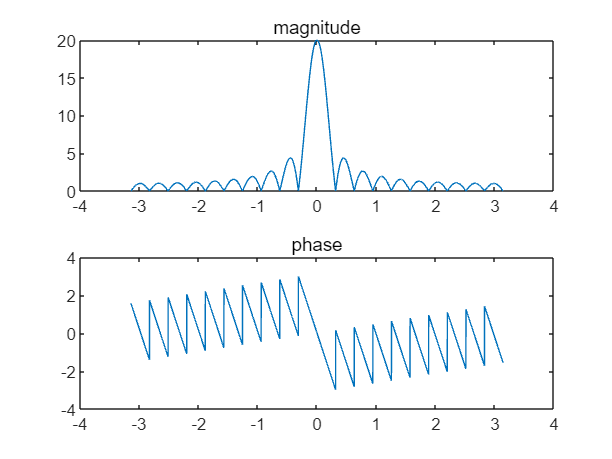

%4.2.3
N=20;
w1=-pi:0.001:0-0.001;
w2=0+0.001:0.001:pi;
w=[w1,0,w2];
W1=(1-exp(-1i*w1*N))./(1-exp(-1i*w1));
W2=(1-exp(-1i*w2*N))./(1-exp(-1i*w2));
W=[W1,N,W2];
x=19/2*w;
figure
subplot(211);
plot(w,abs(W));
title('magnitude');
subplot(212);
plot(w,phase(W));%为什么图像是这样？
title('phase');

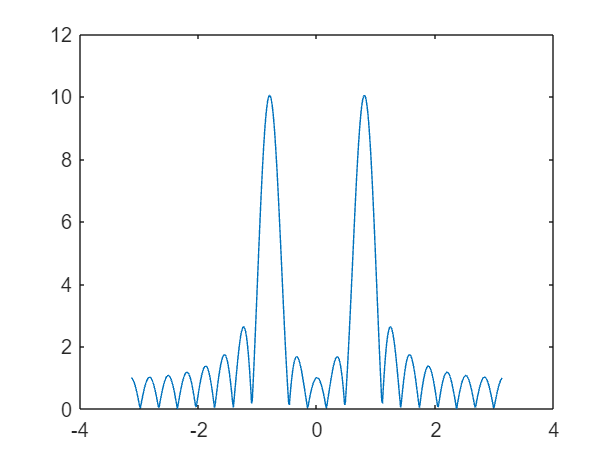

%N=32;
n=0:N-1;
x=cos(pi/4*n);
[X,w]=DTFT(x,512);
figure;
plot(w,abs(X));

% a=DFTsum(x);
% figure
% stem(n,abs(a));

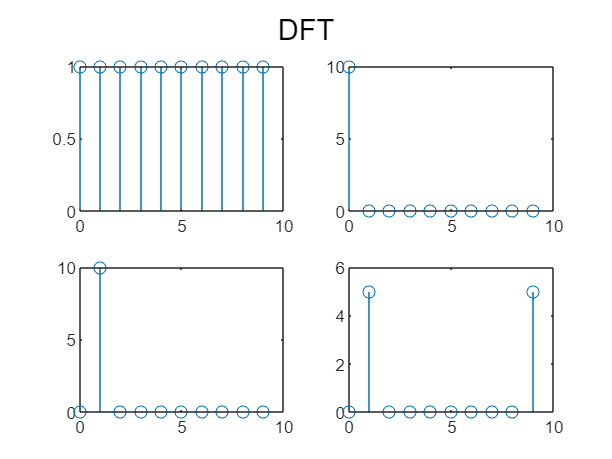

%4.3.1
%DFT
N=10;
n=0:N-1;
x1=(n==0);
x2=ones(1,N);
x3=exp(1i*2*pi*n/10);
x4=cos(2*pi*n/10);
X1=DFTsum(x1);
X2=DFTsum(x2);
X3=DFTsum(x3);
X4=DFTsum(x4);
figure;
subplot(2,2,1);
stem(n,abs(X1));
subplot(2,2,2);
stem(n,abs(X2));
subplot(2,2,3);
stem(n,abs(X3));
subplot(2,2,4);
stem(n,abs(X4));
sgtitle('DFT')

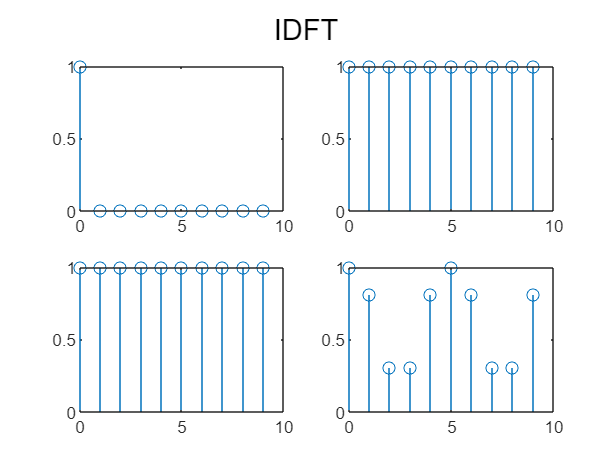


%IDFT
x1_=IDFTsum(X1);
x2_=IDFTsum(X2);
x3_=IDFTsum(X3);
x4_=IDFTsum(X4);
figure;
subplot(2,2,1);
stem(n,abs(x1_));
subplot(2,2,2);
stem(n,abs(x2_));
subplot(2,2,3);
stem(n,abs(x3_));
subplot(2,2,4);
stem(n,abs(x4_));
sgtitle('IDFT')

%4.3.2
%DFTmatrix
A=DFTmatrix(5)

A =   1.000000000000000 + 0.000000000000000i  1.000000000000000 + 0.000000000000000i  1.000000000000000 + 0.000000000000000i  1.000000000000000 + 0.000000000000000i  1.000000000000000 + 0.000000000000000i
  1.000000000000000 + 0.000000000000000i  0.309016994374947 - 0.951056516295154i -0.809016994374947 - 0.587785252292473i -0.809016994374947 + 0.587785252292473i  0.309016994374947 + 0.951056516295154i
  1.000000000000000 + 0.000000000000000i -0.809016994374947 - 0.587785252292473i  0.309016994374947 + 0.951056516295154i  0.309016994374948 - 0.951056516295154i -0.809016994374948 + 0.587785252292473i
  1.000000000000000 + 0.000000000000000i -0.809016994374947 + 0.587785252292473i  0.309016994374948 - 0.951056516295154i  0.309016994374947 + 0.951056516295154i -0.809016994374947 - 0.587785252292474i
  1.000000000000000 + 0.000000000000000i  0.309016994374947 + 0.951056516295154i -0.809016994374948 + 0.587785252292473i -0.809016994374947 - 0.587785252292474i  0.309016994374948 - 0.95105651

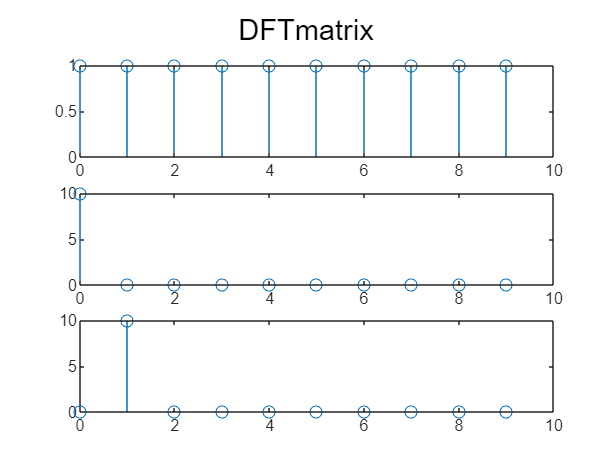

N=10;
n=0:N-1;
x1=(n==0);
x2=ones(1,N);
x3=exp(1i*2*pi*n/N);
A1=DFTmatrix(N);
X1 = A1*x1.';
X2 = A1*x2.';
X3 = A1*x3.';
figure;
subplot(3,1,1);
stem(n,abs(X1));
subplot(3,1,2);
stem(n,abs(X2));
subplot(3,1,3);
stem(n,abs(X3));
sgtitle('DFTmatrix')


%IDFTmatrix
B=IDFTmatrix(5)

B =   0.200000000000000 + 0.000000000000000i  0.200000000000000 + 0.000000000000000i  0.200000000000000 + 0.000000000000000i  0.200000000000000 + 0.000000000000000i  0.200000000000000 + 0.000000000000000i
  0.200000000000000 + 0.000000000000000i  0.061803398874989 + 0.190211303259031i -0.161803398874989 + 0.117557050458495i -0.161803398874989 - 0.117557050458495i  0.061803398874989 - 0.190211303259031i
  0.200000000000000 + 0.000000000000000i -0.161803398874989 + 0.117557050458495i  0.061803398874989 - 0.190211303259031i  0.061803398874990 + 0.190211303259031i -0.161803398874990 - 0.117557050458495i
  0.200000000000000 + 0.000000000000000i -0.161803398874989 - 0.117557050458495i  0.061803398874990 + 0.190211303259031i  0.061803398874989 - 0.190211303259031i -0.161803398874989 + 0.117557050458495i
  0.200000000000000 + 0.000000000000000i  0.061803398874989 - 0.190211303259031i -0.161803398874990 - 0.117557050458495i -0.161803398874989 + 0.117557050458495i  0.061803398874990 + 0.19021130

C=B*A

C =   1.000000000000000 + 0.000000000000000i -0.000000000000000 - 0.000000000000000i -0.000000000000000 - 0.000000000000000i  0.000000000000000 - 0.000000000000000i  0.000000000000000 - 0.000000000000000i
 -0.000000000000000 + 0.000000000000000i  1.000000000000000 - 0.000000000000000i -0.000000000000000 - 0.000000000000000i  0.000000000000000 - 0.000000000000000i  0.000000000000000 - 0.000000000000000i
  0.000000000000000 + 0.000000000000000i -0.000000000000000 + 0.000000000000000i  1.000000000000000 - 0.000000000000000i -0.000000000000000 - 0.000000000000000i -0.000000000000000 - 0.000000000000000i
  0.000000000000000 + 0.000000000000000i  0.000000000000000 + 0.000000000000000i  0.000000000000000 - 0.000000000000000i  1.000000000000000 + 0.000000000000000i -0.000000000000000 - 0.000000000000000i
  0.000000000000000 + 0.000000000000000i  0.000000000000000 + 0.000000000000000i -0.000000000000000 + 0.000000000000000i -0.000000000000000 + 0.000000000000000i  1.000000000000000 + 0.00000000

%4.3.3
format long
N=512;
n=0:N-1;
x=cos(2*pi*n/10);
A=DFTmatrix(N);
t1=cputime;
X1=DFTsum(x);
t1=cputime-t1

t1 =      0


t2=cputime;
X2=A*x.';
t2=cputime-t2

t2 =      0


y = [-14 - 5j, -3 - 17j, -2 + 5j, -9.73 + 12.5j, 5.8 + 5.67j];
h = [3 + 2j, -1 + 4j, 2 + 1j];
x = deconv(y,h);
y = [-1, -1, 11, -3, 35, 29, 65];
h = [-1, 2, 3, 5];
x = deconv(y,h);

g = [-3 2 4 0];
h = [2 -4 0 1];
G = DFTsum(g)

G =    3.0000 + 0.0000i  -7.0000 - 2.0000i  -1.0000 + 0.0000i  -7.0000 + 2.0000i


H = DFTsum(h)

H =   -1.0000 + 0.0000i   2.0000 + 5.0000i   5.0000 + 0.0000i   2.0000 - 5.0000i


Y = G.*H

Y =   -3.0000 + 0.0000i  -4.0000 -39.0000i  -5.0000 + 0.0000i  -4.0000 +39.0000i


y =IDFTsum(Y)

y =   -4.0000 + 0.0000i  20.0000 + 0.0000i   0.0000 + 0.0000i -19.0000 + 0.0000i
